clear;

% Taylor
syms T(x) Tp(x) x e

T(x) = e + 2*e*(x-0.5) + 2*e*(x-0.5)^2 + 4/3*e*(x-0.5)^3 + 2/3*e*(x-0.5)^4;
T(x) = simplify(T(x))

$$T(x) = \frac{e\,\left(16\,x^{4}+24\,x^{2}+16\,x+9\right)}{24}$$

Tp(x) = diff(T(x), x);
Tp(x) = simplify(Tp(x))

$$Tp(x) = \frac{2\,e\,\left(4\,x^{3}+3\,x+1\right)}{3}$$

T(x) = subs(T(x), e, exp(1));
Tp(x) = subs(Tp(x), e, exp(1));

% Lagrange
syms L(x) Lp(x) x e 

x0 = 0; x1 = 0.5; x2 = -0.5; x3 = 1; x4 = -1;

L0 = (x-x1)*(x-x2)*(x-x3)*(x-x4) / ( (x0-x1)*(x0-x2)*(x0-x3)*(x0-x4) );
L1 = (x-x0)*(x-x2)*(x-x3)*(x-x4) / ( (x1-x0)*(x1-x2)*(x1-x3)*(x1-x4) );
L2 = (x-x0)*(x-x1)*(x-x3)*(x-x4) / ( (x2-x0)*(x2-x1)*(x2-x3)*(x2-x4) );
L3 = (x-x0)*(x-x1)*(x-x2)*(x-x4) / ( (x3-x0)*(x3-x1)*(x3-x2)*(x3-x4) );
L4 = (x-x0)*(x-x1)*(x-x2)*(x-x3) / ( (x4-x0)*(x4-x1)*(x4-x2)*(x4-x3) );

L(x) = L0 + e^(1/2)*L1 + e^(-1/2)*L2 + e*L3 + e^(-1)*L4;
L(x) = collect(L(x))

$$L(x) = \begin{array}{l} \left(\frac{2\,e}{3}+\frac{2}{3\,e}-\sigma_{2}-\sigma_{1}+4\right)\,x^{4}+\left(\frac{2\,e}{3}-\frac{2}{3\,e}+\sigma_{4}-\sigma_{3}\right)\,x^{3}+\left(\sigma_{2}-\frac{1}{6\,e}-\frac{e}{6}+\sigma_{1}-5\right)\,x^{2}+\left(\frac{1}{6\,e}-\frac{e}{6}-\sigma_{4}+\sigma_{3}\right)\,x+1\\ \mathrm{where}\\ \sigma_{1}=\frac{8\,\sqrt{e}}{3}\\ \sigma_{2}=\frac{8}{3\,\sqrt{e}}\\ \sigma_{3}=\frac{4\,\sqrt{e}}{3}\\ \sigma_{4}=\frac{4}{3\,\sqrt{e}} \end{array}$$

Lp(x) = diff(L(x), x);
Lp(x) = collect(Lp(x))

$$Lp(x) = \left(\frac{8\,e}{3}+\frac{8}{3\,e}-\frac{32}{3\,\sqrt{e}}-\frac{32\,\sqrt{e}}{3}+16\right)\,x^{3}+\left(2\,e-\frac{2}{e}+\frac{4}{\sqrt{e}}-4\,\sqrt{e}\right)\,x^{2}+\left(\frac{16}{3\,\sqrt{e}}-\frac{1}{3\,e}-\frac{e}{3}+\frac{16\,\sqrt{e}}{3}-10\right)\,x+\frac{1}{6\,e}-\frac{e}{6}-\frac{4}{3\,\sqrt{e}}+\frac{4\,\sqrt{e}}{3}$$

L(x) = subs(L(x), e, exp(1));
Lp(x) = subs(Lp(x), e, exp(1));

% Chebyshev
syms C(x) Cp(x) x e

x0 = cos(pi/8); x1 = cos(3*pi/8); x2 = cos(5*pi/8); x3 = cos(7*pi/8);

L0 = (x-x1)*(x-x2)*(x-x3) / ((x0-x1)*(x0-x2)*(x0-x3));
L1 = (x-x0)*(x-x2)*(x-x3) / ((x1-x0)*(x1-x2)*(x1-x3));
L2 = (x-x0)*(x-x1)*(x-x3) / ((x2-x0)*(x2-x1)*(x2-x3));
L3 = (x-x0)*(x-x1)*(x-x2) / ((x3-x0)*(x3-x1)*(x3-x2));

C(x) = exp(x0)*L0 + exp(x1)*L1 + exp(x2)*L2 + exp(x3)*L3;
C(x) = collect(C(x));
Cp(x) = diff(C(x), x);
Cp(x) = collect(Cp(x));

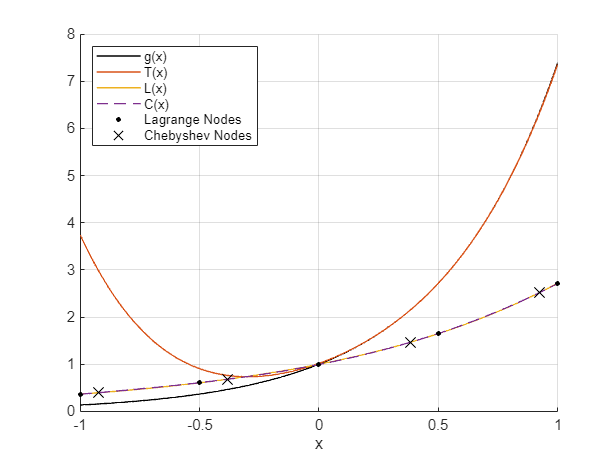

% Plot
X = linspace(-1, 1, 1000);
xL = [-1 -0.5 0 0.5 1];
xC = [cos(pi/8) cos(3*pi/8) cos(5*pi/8) cos(7*pi/8)];

f = figure();
grid on;
legend('Location', 'northwest');
xlabel('x');

hold on;
plot(X, exp(2*X), 'k-', 'LineWidth', 1, ...
    'DisplayName', "g(x)");
plot(X, T(X), '-', 'LineWidth', 1, ...
    'DisplayName', "T(x)");
plot(X, L(X), '-', 'LineWidth', 1, ...
    'DisplayName', "L(x)");
plot(X, C(X), '--', 'LineWidth', 1,...
    'DisplayName', "C(x)");

plot(xL, L(xL), 'k.', 'MarkerSize', 10, ...
    'DisplayName', "Lagrange Nodes");
plot(xC, C(xC), 'kx', 'MarkerSize', 10, ...
    'DisplayName', "Chebyshev Nodes");
hold off;
% exportgraphics(f, 'figures/HW0_q4.png')